clear; clc ;close all
import robo.*
function R_z = Rz(x)
R_z = [cos(x) -sin(x) 0;
    sin(x) cos(x) 0;
    0 0 1]
end

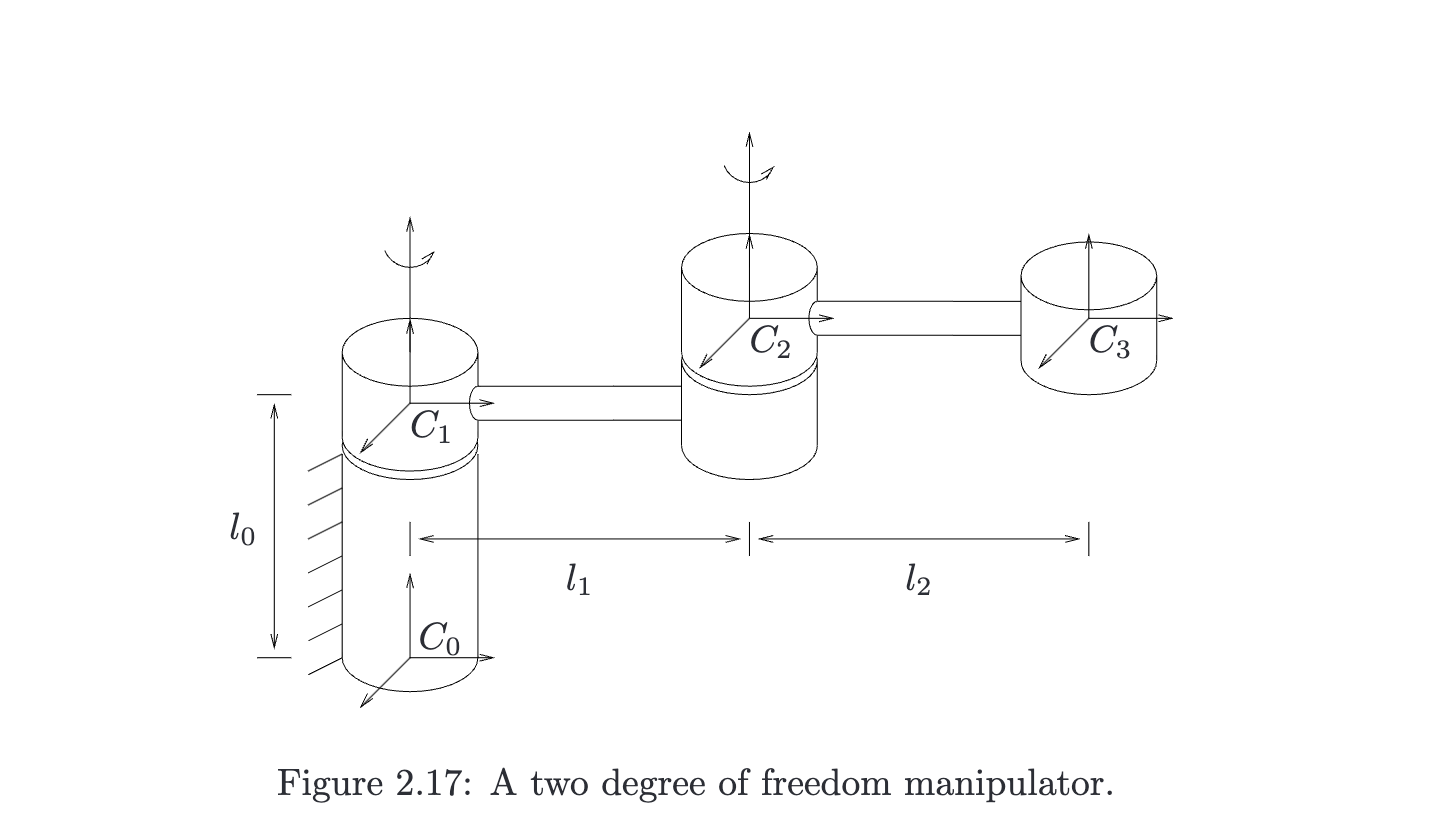

Problem 16. Figure 2.17 shows a two degree of freedom manipulator. Let l0, l1, l2 be the link length parameters and θ1, θ2 the joint angle variables of link 1 and link 2, respectively. 

- (a) Express the position and orientation of frame C3 relative to frame C0 in terms of the joint angle variables and the link parameters

- b) Compute the spatial velocity of C3 relative to C0 as functions of the joint angles and the joint rates. 

- (c) Compute the body velocity of C3 relative to C0 as functions of the joint angles and the joint rates. 

- (d) Optional: Find the spatial velocity of the origin of C3 and use this to check your answer for parts (b) and (c). You may want to use a symbolic math package, such as the one described in Appendix B, to carry out the computations in this exercise.

% 假设C0 是spatial frame 表示出来C3
syms t l0 l1 l2 real ;
syms theta1(t) theta2(t) % 注意，theta1(t) theta2(t) 后面不能接‘real’
h = 0 %由于纯螺旋运动没有平移，什么是平移（活塞类似的）

h = 0

%这里用body frame 变换 homo-trans 
p01 = [0;0;l0];
g01 = gmat(Rz(theta1),p01)

$$R\_z(t) = \left(\begin{array}{ccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$g01(t) = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p12 = [0;l1;0];
g12 = gmat(Rz(theta2),p12)

$$R\_z(t) = \left(\begin{array}{ccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$g12(t) = \left(\begin{array}{cccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0 & l_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p23 = [0;l2;0];
g23 = gmat(eye(3),p23)

$$g23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% using exponential methods like MLS_ex_2_6

omega = [0;0;1] % this unit vector represent the rotational direction of joint in pure z direction

omega =      0
     0
     1


omega1 = [0;0;1];
omega2 = [0;0;1];
omega3 = [0;0;1];


exp_theta1 = rodrigues(omega1,theta1)

$$exp\_theta1(t) = \left(\begin{array}{ccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

exp_theta2 = rodrigues(omega2,theta2)

$$exp\_theta2(t) = \left(\begin{array}{ccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

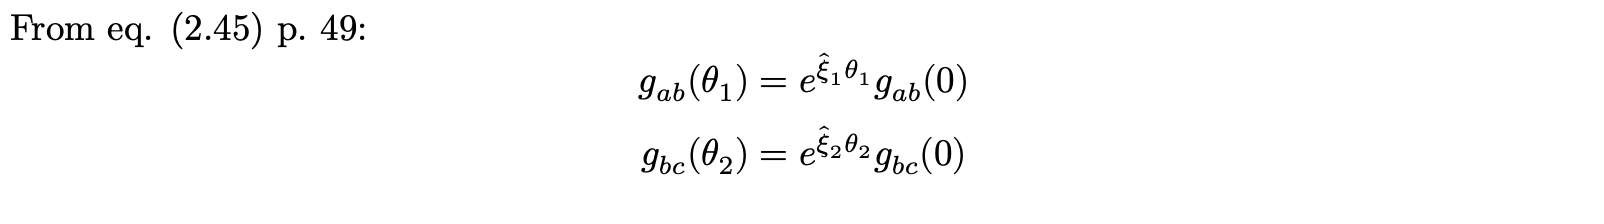

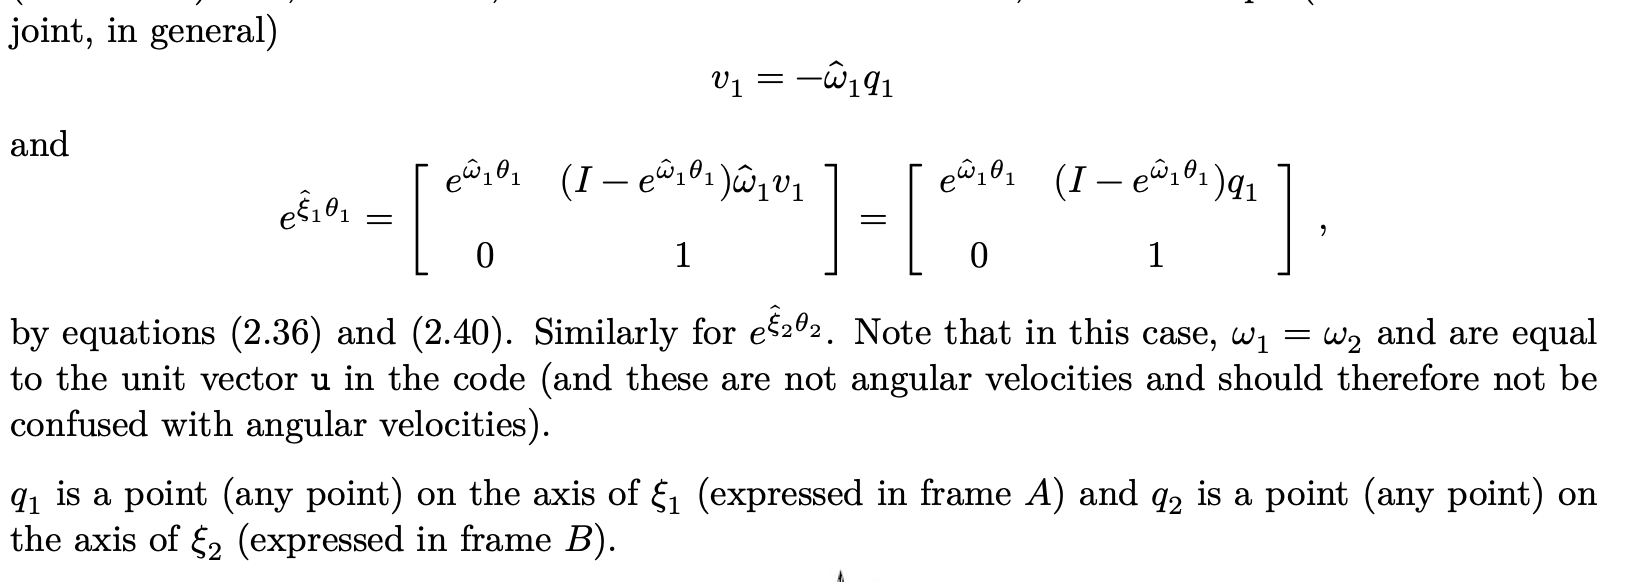

q1 = [0;0;0]; % represent any point in rotational axis 1
q2 = [0;l1;0]; % represent any point in rotational axis 2
q3 = [0;l2;0]

$$q3 = \left(\begin{array}{c} 0\\ l_{2}\\ 0 \end{array}\right)$$


v1 = -hatm(omega1)* q1;
v2 = -hatm(omega2)* q2;
v3 = -hatm(omega3)* q3;

xi_1 = [v1; omega1]; % twist1
xi_2 = [v2; omega2]; % twist2 这里面暂时有一个符号l1，所以她的解不是纯double
xi_3 = [v3; omega3]

$$xi\_3 = \left(\begin{array}{c} l_{2}\\ 0\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$



twist_exp1 = exp_se3(xi_1,theta1) %换层e^{xi * theta}

$$twist\_exp1(t) = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

twist_exp2 = exp_se3(xi_2,theta2)

$$twist\_exp2(t) = \left(\begin{array}{cccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0 & l_{1}\,\sin\left(\theta_{2}\left(t\right)\right)\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0 & -l_{1}\,\left(\cos\left(\theta_{2}\left(t\right)\right)-1\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

twist_exp3 = exp_se3(xi_3,0)

$$twist\_exp3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


g_t01 = gmat(eye(3),p01); %这个是exp 方法的特殊写法跟homo不一样
g_t12 = gmat(eye(3),p12); %注意这里的g_12(0)的写法
g_t23 = gmat(eye(3),p23);
twist_g01 = twist_exp1 * g_t01

$$twist\_g01(t) = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

twist_g12 = twist_exp2 * g_t12

$$twist\_g12(t) = \left(\begin{array}{cccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0 & l_{1}\,\cos\left(\theta_{2}\left(t\right)\right)-l_{1}\,\left(\cos\left(\theta_{2}\left(t\right)\right)-1\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

twist_g23 = twist_exp3 * g_t23

$$twist\_g23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### (a) Express the position and orientation of frame C3 relative to frame C0 in terms of the joint angle variables and the link parameters

%1）homo-trans

G_03=(simplify(g01 *g12*g23))

$$G\_03(t) = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & -l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-l_{2}\,\sigma_{1}\\ \sigma_{1} & \sigma_{2} & 0 & l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{2}\,\sigma_{2}\\ 0 & 0 & 1 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right) \end{array}$$

G_03 = G_03(t)%一定要这样处理一下，不然处理不了

$$G\_03 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & -l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-l_{2}\,\sigma_{1}\\ \sigma_{1} & \sigma_{2} & 0 & l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{2}\,\sigma_{2}\\ 0 & 0 & 1 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right) \end{array}$$

G_03_twist = simplify(twist_g01 *twist_g12 *twist_g23);
Shouldbezero = G_03_twist -G_03 % 验证两个方法出来的结果一样

$$Shouldbezero(t) = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

#### b) Compute the spatial velocity of C3 relative to C0 as functions of the joint angles and the joint rates. 

R03 = G_03(1:3,1:3);
p03 = G_03(1:3,4);
G_03_dot = simplify(diff(G_03,t));
R03_dot = G_03_dot(1:3,1:3);
p03_dot = G_03_dot(1:3,4);


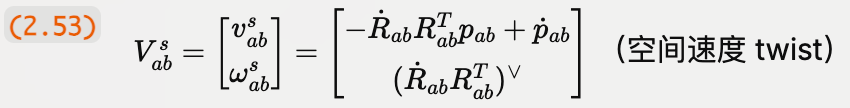

V_hat_spatial = simplify(G_03_dot * inv(G_03))

$$V\_hat\_spatial = \left(\begin{array}{cccc} 0 & -\frac{\partial }{\partial t}\theta_{1}\left(t\right)-\frac{\partial }{\partial t}\theta_{2}\left(t\right) & 0 & l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right) & 0 & 0 & l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$


v_ab_spatial = simplify(-R03_dot*R03'*p03 + p03_dot)

$$v\_ab\_spatial = \begin{array}{l} \left(\begin{array}{c} \sigma_{5}\,\sigma_{2}\,\sigma_{1}+\sigma_{4}\,\sigma_{1}\,\sigma_{3}-l_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\sigma_{1}-l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \sigma_{5}\,\sigma_{1}\,\sigma_{3}-\sigma_{4}\,\sigma_{2}\,\sigma_{1}-l_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\sigma_{1}-l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \sigma_{2}=l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\\ \sigma_{3}=l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+l_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\\ \sigma_{4}=\sin\left(\bar{\theta_{1}\left(t\right)}+\bar{\theta_{2}\left(t\right)}-\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ \sigma_{5}=\cos\left(\bar{\theta_{1}\left(t\right)}+\bar{\theta_{2}\left(t\right)}-\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right) \end{array}$$

omega_ab_spatial = simplify(vee_so3(R03_dot*inv(R03)))

$$omega\_ab\_spatial = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right)$$


% 这就是 (b) 问最终要求的 Spatial Velocity 向量
V_spatial = [v_ab_spatial; omega_ab_spatial];

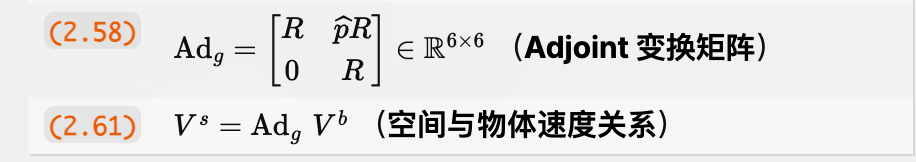

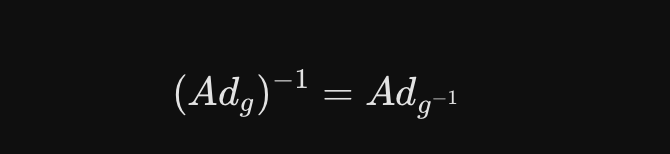

V_body = inv(adjoint(G_03)) * V_spatial

$$V\_body = \begin{array}{l} \left(\begin{array}{c} \frac{\cos\left(\sigma_{8}\right)\,\sigma_{1}}{\sigma_{3}}-\frac{\sigma_{4}\,\left(l_{2}\,{\cos\left(\sigma_{8}\right)}^{2}+l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\sigma_{8}\right)+l_{2}\,{\sin\left(\sigma_{8}\right)}^{2}+l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\sigma_{8}\right)\right)}{\sigma_{3}}-\frac{\sin\left(\sigma_{8}\right)\,\sigma_{2}}{\sigma_{3}}\\ \frac{\left(l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\sigma_{8}\right)-l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\cos\left(\sigma_{8}\right)\right)\,\sigma_{4}}{\sigma_{3}}-\frac{\cos\left(\sigma_{8}\right)\,\sigma_{2}}{\sigma_{3}}-\frac{\sin\left(\sigma_{8}\right)\,\sigma_{1}}{\sigma_{3}}\\ 0\\ 0\\ 0\\ \sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\sigma_{5}\right)\,\sigma_{6}\,\sigma_{4}+\sin\left(\sigma_{5}\right)\,\sigma_{4}\,\sigma_{7}-l_{2}\,\cos\left(\sigma_{8}\right)\,\sigma_{4}-l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \sigma_{2}=\sin\left(\sigma_{5}\right)\,\sigma_{6}\,\sigma_{4}-\cos\left(\sigma_{5}\right)\,\sigma_{4}\,\sigma_{7}+l_{2}\,\sin\left(\sigma_{8}\right)\,\sigma_{4}+l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \sigma_{3}={\cos\left(\sigma_{8}\right)}^{2}+{\sin\left(\sigma_{8}\right)}^{2}\\ \sigma_{4}=\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \sigma_{5}=\bar{\theta_{1}\left(t\right)}+\bar{\theta_{2}\left(t\right)}-\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\\ \sigma_{6}=l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{2}\,\cos\left(\sigma_{8}\right)\\ \sigma_{7}=l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+l_{2}\,\sin\left(\sigma_{8}\right)\\ \sigma_{8}=\theta_{1}\left(t\right)+\theta_{2}\left(t\right) \end{array}$$